s_0 =10^2

s_0 = 100

t_span = [-0.05,0.2];
tol = 10^-6;
N_max = 10;
N_ort = 100;
N_Zeit = 100;
y_a = zeros(N_ort+1,1)

y_a =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


c = konstanten;
z_a = linspace(0,0.3,N_ort+1);
@fd_4

ans = function_handle with value:
    @fd_4


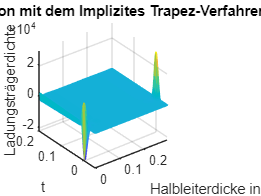


% func = @(t,z) s_0.*exp(-(t.^2)./(2*0.01^2)).*exp(-c.a*z);
% func_simu = @(t,u) fd_nonlin(u,N_ort) + func(t,z);
% d_func_simu = @(t,u) fd_nonlin_jac(u,N_ort);

[Trapez_T,Trapez_Y]=impl_trapez(@fd_4 ,t_span ,y_a ,N_Zeit ,@fd_4_jac ,tol ,N_max);

mesh(z_a,Trapez_T,Trapez_Y);

% mesh(X,Y,Z) erstellt eine Mesh-Darstellung
% d.h. eine dreidimensionale Fläche mit einfarbigen
% Kantenfarben und ohne Flächenfarben.

title('Simulation mit dem Implizites Trapez-Verfahren')
xlabel('Halbleiterdicke in z')
ylabel('t')
zlabel('Ladungsträgerdichte')